# Part 2: Reconeixement

Lectura del directori

close all
Idir = dir('./MotorcycleChase/img/*.jpg');
addpath("./methods");

Dividim totes les imatges entre dos.

% dirScaling("./MotorcycleChase/img/");

Lectura del fitxer d'annotacions. Segueix el següent format:

[ID del frame, xmin, ymin, amplada, alçada, isLost] 

on cada ítem indica: frameID: 

- numero de frame. 

- xmin - Coordenada x superior esquerra del quadre delimitador. 

- ymin - Coordenada y superior esquerra del quadre delimitador. 

- amplada - Amplada del quadre. 

- altura - Alçada del quadre.

- isLost - Si és 1, l'objecte objectiu no és visible en absolut; altrament 0

BB = importdata('./MotorcycleChase/groundtruth_rect.txt'); 
% 1,495,343,172,109,0
InitialObjectPosition = [BB(1,2) BB(1,3) BB(1,4) BB(1,5)];

Imatge de l'objecte a identificar.

filename = horzcat(Idir(1).folder,'/',Idir(1).name);
I = imread(filename);

% objecte a reconèixer
imObj = rgb2gray(imcrop(I, InitialObjectPosition));
kpObj = detectSIFTFeatures(imObj);
kpObj  =selectStrongest(kpObj,50);
[featuresObj, kpObj] = extractFeatures(imObj, kpObj, "Method","SIFT");

% object box for later calculation
[f,c] = size(imObj);
box = [1,1; 1,f; c,f; c,1];

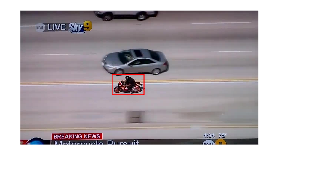

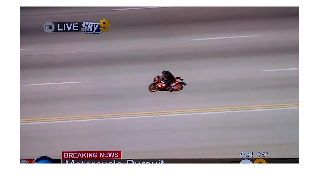

Error using vision.internal.geotrans.algEstimateGeometricTransform>checkRuntimeStatus
Could not find enough inliers in matchedPoints1 and matchedPoints2.

Error in vision.internal.geotrans.algEstimateGeometricTransform (line 72)
    checkRuntimeStatus(statusCode, status, sampleSize);

Error in 

nf = size(Idir); % nombre total de fitxers imatges
figure
hold on
for i = 1:(nf-1)
    filename = horzcat(Idir(i).folder,'/',Idir(i).name);
    frame = imread(filename);
    % escena pel reconeixement
    imScn = rgb2gray(frame);
    kpScn = detectSIFTFeatures(imScn);
    kpScn  =selectStrongest(kpScn,50);
    [featuresScn, kpScn] = extractFeatures(imScn, kpScn, "Method","SIFT");
    
    % matching
    pairs = matchFeatures(featuresObj, featuresScn, "MatchThreshold",50);
    matching_kpObj = kpObj(pairs(:,1),:);
    matching_kpScn = kpScn(pairs(:,2),:);
    
    numPoints = size(matching_kpScn, 1);
    
    [T, ~, ~, status]  = estimateGeometricTransform2D(matching_kpObj,matching_kpScn, "affine");
    nbox = transformPointsForward(T, box);

    minX = min(nbox(:, 1));
    maxX = max(nbox(:, 1));
    minY = min(nbox(:, 2));
    maxY = max(nbox(:, 2));
    
    % Calcular el ancho y alto del rectángulo
    width = maxX - minX;
    height = maxY - minY;

    % Crear el rectángulo
    rect = [minX, minY, width, height];

    imshow(frame);
    rectangle('Position', rect, 'EdgeColor', 'r');
    drawnow
end

disp("Finished Successfully");